# It's a MAP

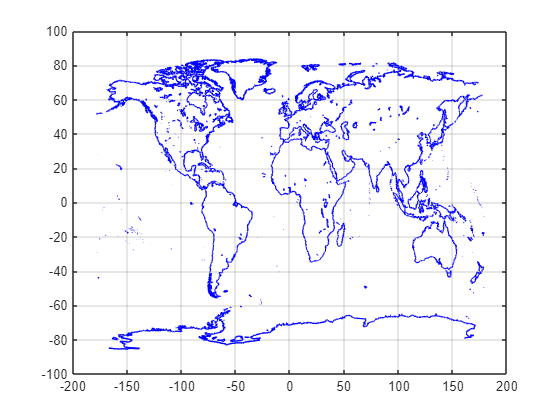

clearvars

map1 = readtable("res\map\map1.csv");
map2 = readtable("res\map\map2.csv");
map3 = readtable("res\map\map3.csv");

mapIt(map1); % NOT FAST.
grid;

% mapIt(map2); % SLOW
% mapIt(map3); % SLOW

function mapIt(mapTable)

    npoints = mapTable.Var1(4);
    color   = mapTable.Var2(4);
    minLon  = mapTable.Var1(5);
    minLat  = mapTable.Var2(5);
    maxLon  = mapTable.Var1(6);
    maxLat  = mapTable.Var2(6);
    strt = 7;
    stop = 7 + npoints-1;
    plot(mapTable.Var1(strt:stop),mapTable.Var2(strt:stop),"b");
    hold on
    
    
    while stop < height(mapTable)
    
        if mapTable.Var2(stop+1) == -999
            npoints = mapTable.Var1(stop+1);
            xolor   = mapTable.Var2(stop+1);
            minLon  = mapTable.Var1(stop+2);
            minLat  = mapTable.Var2(stop+2);
            maxLon  = mapTable.Var1(stop+3);
            maxLat  = mapTable.Var2(stop+3);
            stop = stop + 3;
        end
        npoints = mapTable.Var1(stop+1);
        color   = mapTable.Var2(stop+1);
        minLon  = mapTable.Var1(stop+2);
        minLat  = mapTable.Var2(stop+2);
        maxLon  = mapTable.Var1(stop+3);
        maxLat  = mapTable.Var2(stop+3);
        strt = stop + 4;
        stop = strt + npoints - 1;
        plot(mapTable.Var1(strt:stop),mapTable.Var2(strt:stop),"b");
    end

end